# Test the MPP

In this workbench we test how well the MPP we extracted performs. First we reproject the calibration points, and then we try with some new points.

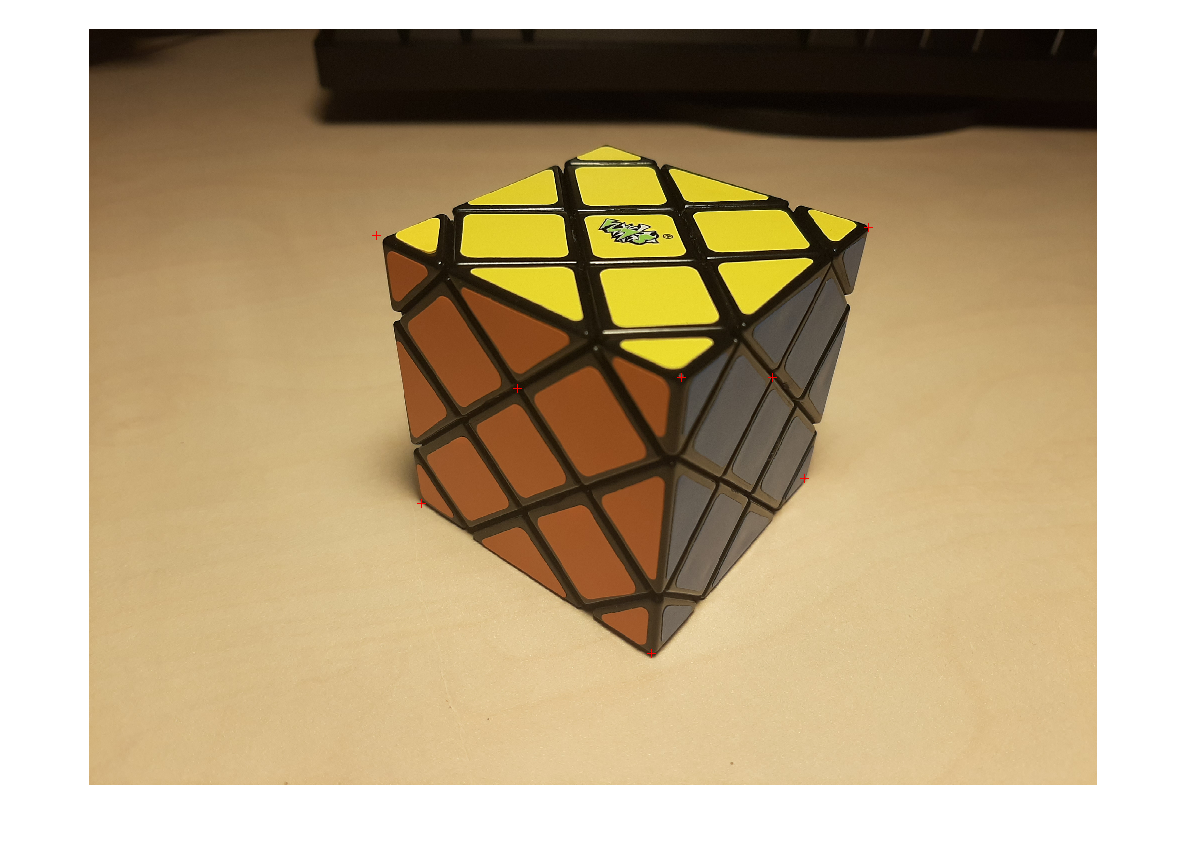

addpath('../0.utils')
calib_path = '../0.calib_results/calib-cube-img_3.mat';
cal = load(calib_path);

% show calibration image
imshow(cal.image), hold on;

% reproject the calibration points
m_test = project(cal.P, cal.M);
scatter(m_test(1,:), m_test(2,:), "+r");


clear calib_path;
h = '';

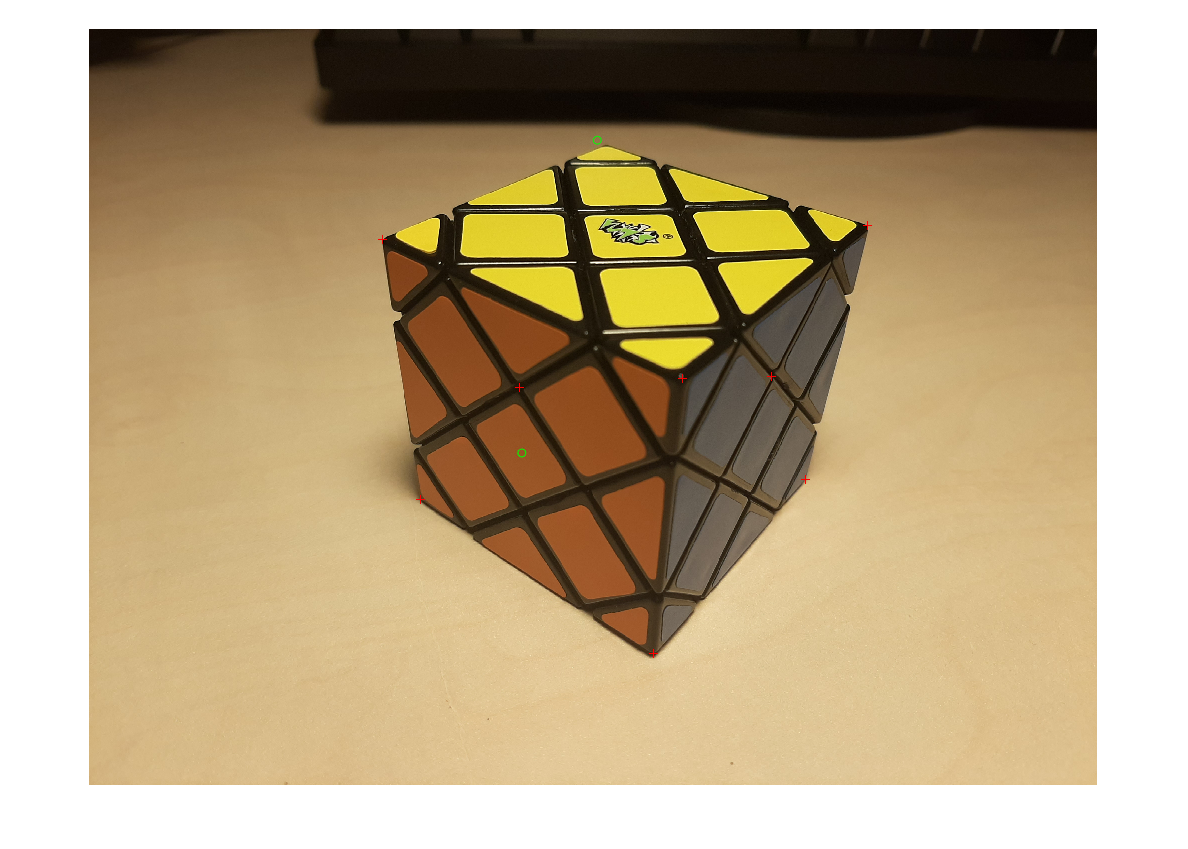

% project new points
delete(h);
M_test = [[0.056 0.056 0.056  1]', [0 0.028 0.028  1]'];
m_test = project(cal.P, M_test);
h = scatter(m_test(1,:), m_test(2,:), "og");


clear m_test M_test;